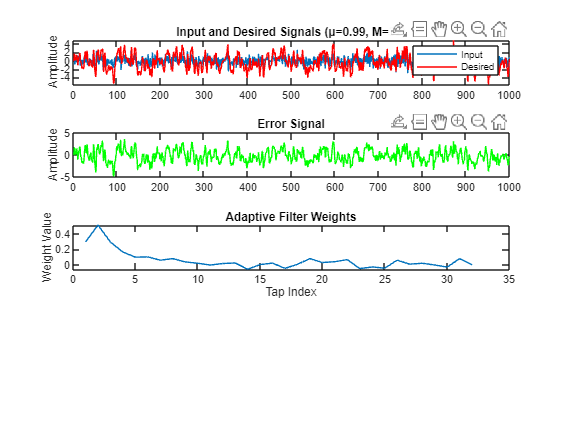

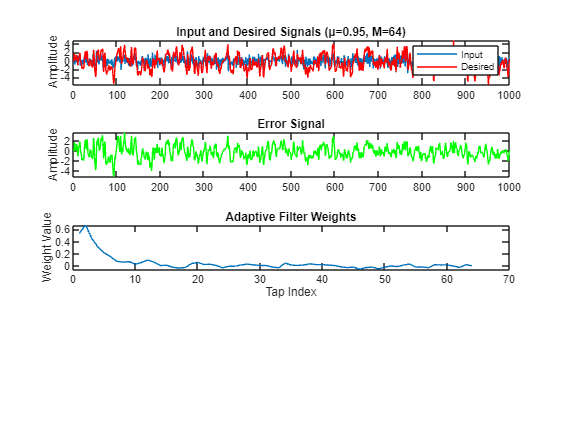

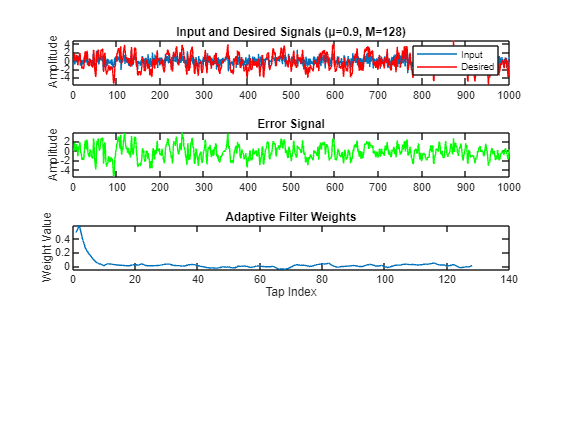

clear all; 
close all; 
clc;

% Parameters for the three significant points
significant_points = [
    struct('mu', 0.99, 'M', 32),  % High μ, Low M
    struct('mu', 0.95, 'M', 64),  % Medium μ, Medium M
    struct('mu', 0.9, 'M', 128)   % Low μ, High M
];

% Initialize variables to store results
results = cell(size(significant_points));

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Loop over the significant points
for i = 1:numel(significant_points)
    mu = significant_points(i).mu;
    M = significant_points(i).M;
    
    % Initialize weight vector and inverse correlation matrix
    w = zeros(M,1);
    P = eye(M)/0.001;

    % Buffers
    x_buf = zeros(M,1);
    y_buf = zeros(length(d),1);

    % Main loop
    tic; % Start timer
    for n = (M+1):length(x)

        % Shift input buffer
        x_buf = x(n:-1:n-M+1); % Fixed indexing

        % FIR filter output
        y = w'*x_buf;
        y_buf(n) = y;

        % Error signal
        e = d(n) - y;

        % Update inverse correlation matrix
        k = P*x_buf / (mu + x_buf'*P*x_buf);
        P = (P - k*x_buf'*P) / (mu + x_buf'*P*x_buf); % Fixed updating formula

        % Update weight vector
        w = w + k*e;

    end
    elapsed_time = toc; % End timer

    % Calculate Signal-to-Noise Ratio (SNR)
    SNR_input = snr(d, d - x); % SNR of input signal
    SNR_output = snr(d, d - y_buf); % SNR of output signal
    
    % Store results
    results{i} = struct(...
        'mu', mu, ...
        'M', M, ...
        'convergence_rate', SNR_output - SNR_input, ...
        'computational_time', elapsed_time, ...
        'SNR_input', SNR_input, ...
        'SNR_output', SNR_output ...
    );
    
    % Plot signals and weights
    figure;
    subplot(4,1,1);
    plot(x); hold on; plot(d,'r'); legend('Input','Desired');
    ylabel('Amplitude');
    title(['Input and Desired Signals (μ=' num2str(mu) ', M=' num2str(M) ')']);

    subplot(4,1,2);
    plot(d-y_buf,'g'); 
    ylabel('Amplitude');
    title('Error Signal');

    subplot(4,1,3);
    plot(w);
    ylabel('Weight Value');
    xlabel('Tap Index');
    title('Adaptive Filter Weights');
end

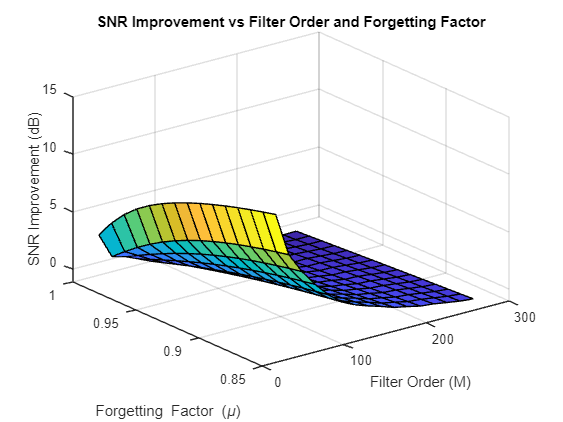


% Define ranges for μ and M
mu_range = 0.85:0.01:0.99;  % Range of μ values
M_range = 16:16:256;         % Range of M values

% Create a grid of μ and M values
[M_grid, mu_grid] = meshgrid(M_range, mu_range);

% Initialize arrays to store SNR improvement
SNR_improvements = zeros(size(M_grid));

% Loop over all μ and M values
for i = 1:numel(mu_range)
    for j = 1:numel(M_range)
        mu = mu_range(i);
        M = M_range(j);
        
        % Initialize weight vector and inverse correlation matrix
        w = zeros(M,1);
        P = eye(M)/0.001;

        % Buffers
        x_buf = zeros(M,1);
        y_buf = zeros(length(d),1);

        % Main loop
        for n = (M+1):length(x)

            % Shift input buffer
            x_buf = x(n:-1:n-M+1); % Fixed indexing

            % FIR filter output
            y = w'*x_buf;
            y_buf(n) = y;

            % Error signal
            e = d(n) - y;

            % Update inverse correlation matrix
            k = P*x_buf / (mu + x_buf'*P*x_buf);
            P = (P - k*x_buf'*P) / (mu + x_buf'*P*x_buf); % Fixed updating formula

            % Update weight vector
            w = w + k*e;

        end

        % Calculate Signal-to-Noise Ratio (SNR)
        SNR_input = snr(d, d - x); % SNR of input signal
        SNR_output = snr(d, d - y_buf); % SNR of output signal
        
        % Store SNR improvement
        SNR_improvements(i, j) = SNR_output - SNR_input;
    end
end

% Plot SNR improvement as a surface plot
figure;
surf(M_grid, mu_grid, SNR_improvements);
xlabel('Filter Order (M)');
ylabel('Forgetting Factor (\mu)');
zlabel('SNR Improvement (dB)');
title('SNR Improvement vs Filter Order and Forgetting Factor');


% Find the point with the highest SNR improvement
SNR_improvements_flat = reshape(SNR_improvements, 1, []);
[max_SNR_improvement, max_index] = max(SNR_improvements_flat);
[best_i, best_j] = ind2sub(size(SNR_improvements), max_index);
best_mu = mu_range(best_i);
best_M = M_range(best_j);

fprintf('Best Point:\n');

Best Point:


fprintf('μ: %.2f, M: %d\n', best_mu, best_M);

μ: 0.85, M: 16
